# Laboratorium 5

Janusz Pawlicki

## 1. Wstęp

### 1.1 Całkowe przekształenie Fouriera

Analiza harmoniczna sygnaªów za pomoc¡ szeregów Fouriera pozwala na badanie właściwości przebiegów wyłącznie okresowych. W praktyce jednak mamy do czynienia z sygnałami, które nie mają charakteru okresowego lub których czas trwania jest ograniczony. W takich sytuacjach analizę częstotliwością można przeprowadzić za pomocą tzw.

ciągłego przekształcenia Fouriera F(x(t)) = X(jω) (1). W odróżnieniu od wyniku analizy harmonicznej (szeregi Fouriera), dziedzina ω ciągłej reprezentacji częstotliwościowej transformaty X(jω) uzyskanej za pomocą przekształcenia Fouriera ma charakter ciągły

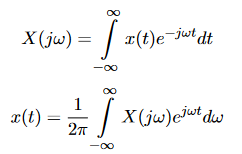

W ogólności, reprezentacja częstotliwościowa ma charkter zespolny dlatego widmo sygnału można przedstawić w równoważnej postaci fazowo-amplitudowej (3) gdzie A(ω) stanowi gęstość widmową amplitudy, zaś φ(ω) gęstość widmową fazy. Wówaczas postać zespolona może być odtworzona w następujący sposób: X(jω) = A(ω)^(ejφ(ω)).

## 2. Przebieg laboratorium

clear all;
close all;

syms t x f0 w w0 X_FT

f0 = 100; %Hz
w0 = 2*pi*f0;

BND_t = [-10/f0;10/f0]; %20 okresow
t_SMP = [BND_t(1):1/(10*f0):BND_t(2) ];

BND_w = [-3*w0;3*w0];
w_SMP = [BND_w(1):w0/10:BND_w(2) ];

%x = sin(w0*t);

% fragment kodu odpowiedzialny za impulsy Diraca
% zakomentowany = 1; odkomentowany = 0
commentSignal = 0;
commentReal = 0;
commentImag = 0;

figure
subplot(3,1,1);
ylabel('x(t)');
hold on
ezplot(x,BND_t);
hold on;
grid on;

if commentSignal == 0
    v_num = subs(x, t, t_SMP);
    n = find(abs(v_num) == inf); % plot dirac (inf)
    stem(t_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
end

subplot(3,1,2);
ylabel('real(X(\omega))');
hold on
if commentReal == 0
    v_num = subs(real(X_FT),w,w_SMP);
    n = find(abs(v_num) == inf); % plot dirac(inf)
    stem(w_SMP(n)/2/pi,pi*sign(v_num(n)), 'r*', 'LineWidth', 2);
end
ezplot(real(X_FT), BND_w); 
hold on;
grid on;


subplot(3,1,3);
ylabel('imag(X(\omega))');
hold on
ezplot(imag(X_FT), BND_w);
if commentImag == 0
    v_num = subs(imag(X_FT),w,w_SMP);
    n = find(abs(v_num) == inf); % plot dirac(inf)
    stem(w_SMP(n)/2/pi,pi/4*sign(v_num(n)), 'r*', 'LineWidth', 2);
end
hold on;
grid on

### 2.1 Zadanie 1

Wykonaj obliczenia oraz wyświetl widmo sygnału sinusoidalnego aby uzyskać wynik jak na rysunku 1

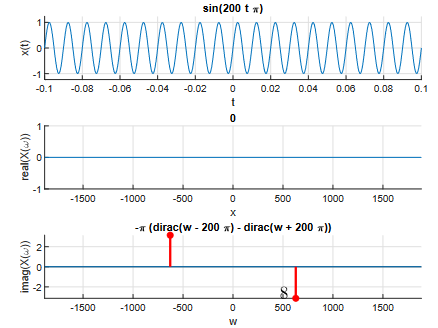

### 2.2 Zadanie 2

Przebadaj działanie ciągłego przekształcenia Fouriera dla poniższych sygnałów:

a) sygnał cos(ω0t),

clear all;
close all;

syms t x f0 w w0 X_FT

f0 = 100; %Hz
w0 = 2*pi*f0;

BND_t = [-10/f0;10/f0]; %20 okresow
t_SMP = [BND_t(1):1/(10*f0):BND_t(2) ];

BND_w = [-3*w0;3*w0];
w_SMP = [BND_w(1):w0/10:BND_w(2) ];

%x = cos(w0*t);

% fragment kodu odpowiedzialny za impulsy Diraca
% zakomentowany = 1; odkomentowany = 0
commentSignal = 0;
commentReal = 0;
commentImag = 0;

figure
subplot(3,1,1);
ylabel('x(t)');
hold on
ezplot(x,BND_t);
hold on;
grid on;

if commentSignal == 0
    v_num = subs(x, t, t_SMP);
    n = find(abs(v_num) == inf); % plot dirac (inf)
    stem(t_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
end

subplot(3,1,2);
ylabel('real(X(\omega))');
hold on
if commentReal == 0
    v_num = subs(real(X_FT),w,w_SMP);
    n = find(abs(v_num) == inf); % plot dirac(inf)
    stem(w_SMP(n)/2/pi,pi*sign(v_num(n)), 'r*', 'LineWidth', 2);
end
ezplot(real(X_FT), BND_w); 
hold on;
grid on;


subplot(3,1,3);
ylabel('imag(X(\omega))');
hold on
ezplot(imag(X_FT), BND_w);
if commentImag == 0
    v_num = subs(imag(X_FT),w,w_SMP);
    n = find(abs(v_num) == inf); % plot dirac(inf)
    stem(w_SMP(n)/2/pi,pi/4*sign(v_num(n)), 'r*', 'LineWidth', 2);
end
hold on;
grid on

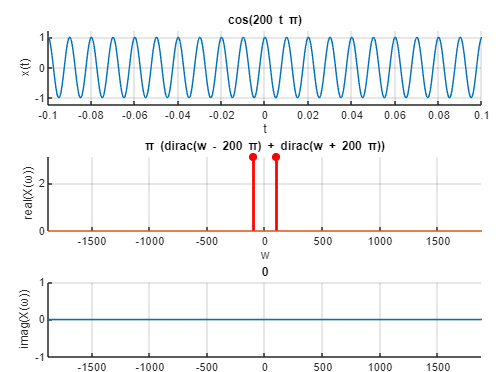

b) sygnał stały o wartości 10 (do jego zdefiniowanie należy użyć polecenia `sym(10)`),

clear all;
close all;

syms t x f0 w w0 X_FT

f0 = 100; %Hz
w0 = 2*pi*f0;

BND_t = [-10/f0;10/f0]; %20 okresow
t_SMP = [BND_t(1):1/(10*f0):BND_t(2) ];

BND_w = [-3*w0;3*w0];
w_SMP = [BND_w(1):w0/10:BND_w(2) ];

%x = sym('10');

% fragment kodu odpowiedzialny za impulsy Diraca
% zakomentowany = 1; odkomentowany = 0
commentSignal = 0;
commentReal = 0;
commentImag = 0;

figure
subplot(3,1,1);
ylabel('x(t)');
hold on
ezplot(x,BND_t);
hold on;
grid on;

if commentSignal == 0
    v_num = subs(x, t, t_SMP);
    n = find(abs(v_num) == inf); % plot dirac (inf)
    stem(t_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
end

subplot(3,1,2);
ylabel('real(X(\omega))');
hold on
if commentReal == 0
    v_num = subs(real(X_FT),w,w_SMP);
    n = find(abs(v_num) == inf); % plot dirac(inf)
    stem(w_SMP(n)/2/pi,pi*sign(v_num(n)), 'r*', 'LineWidth', 2);
end
ezplot(real(X_FT), BND_w); 
hold on;
grid on;


subplot(3,1,3);
ylabel('imag(X(\omega))');
hold on
ezplot(imag(X_FT), BND_w);
if commentImag == 0
    v_num = subs(imag(X_FT),w,w_SMP);
    n = find(abs(v_num) == inf); % plot dirac(inf)
    stem(w_SMP(n)/2/pi,pi/4*sign(v_num(n)), 'r*', 'LineWidth', 2);
end
hold on;
grid on

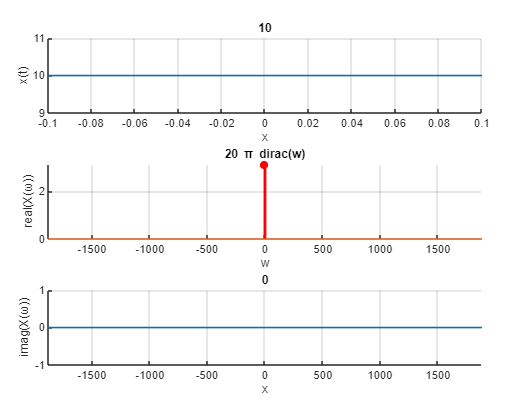

c) skok jednostkowy o amplitudzie 1,

clear all;
close all;

syms t x f0 w w0 X_FT

f0 = 100; %Hz
w0 = 2*pi*f0;

BND_t = [-10/f0;10/f0]; %20 okresow
t_SMP = [BND_t(1):1/(10*f0):BND_t(2) ];

BND_w = [-3*w0;3*w0];
w_SMP = [BND_w(1):w0/10:BND_w(2) ];

%x = heaviside(t);

% fragment kodu odpowiedzialny za impulsy Diraca
% zakomentowany = 1; odkomentowany = 0
commentSignal = 0;
commentReal = 0;
commentImag = 0;

figure
subplot(3,1,1);
ylabel('x(t)');
hold on
ezplot(x,BND_t);
hold on;
grid on;

if commentSignal == 0
    v_num = subs(x, t, t_SMP);
    n = find(abs(v_num) == inf); % plot dirac (inf)
    stem(t_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
end

subplot(3,1,2);
ylabel('real(X(\omega))');
hold on
if commentReal == 0
    v_num = subs(real(X_FT),w,w_SMP);
    n = find(abs(v_num) == inf); % plot dirac(inf)
    stem(w_SMP(n)/2/pi,pi*sign(v_num(n)), 'r*', 'LineWidth', 2);
end
ezplot(real(X_FT), BND_w); 
hold on;
grid on;


subplot(3,1,3);
ylabel('imag(X(\omega))');
hold on
ezplot(imag(X_FT), BND_w);
if commentImag == 0
    v_num = subs(imag(X_FT),w,w_SMP);
    n = find(abs(v_num) == inf); % plot dirac(inf)
    stem(w_SMP(n)/2/pi,pi/4*sign(v_num(n)), 'r*', 'LineWidth', 2);
end
hold on;
grid on

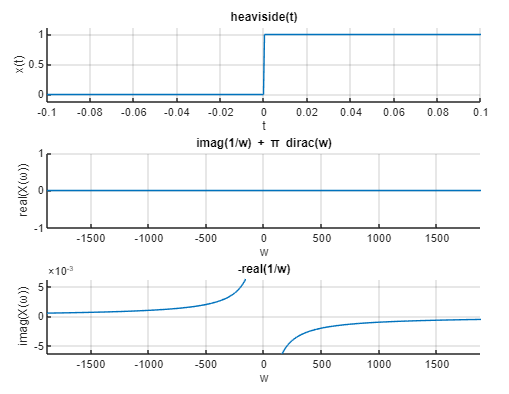

d) impuls prostokątny o amplitudzie 1 oraz czasie trwania Ti = 2/f`0` ,

clear all;
close all;

syms t x f0 w w0 X_FT

f0 = 100; %Hz
w0 = 2*pi*f0;

BND_t = [-10/f0;10/f0]; %20 okresow
t_SMP = [BND_t(1):1/(10*f0):BND_t(2) ];

BND_w = [-3*w0;3*w0];
w_SMP = [BND_w(1):w0/10:BND_w(2) ];

%x = rectangularPulse(-1/f0, 1/f0, t);

% fragment kodu odpowiedzialny za impulsy Diraca
% zakomentowany = 1; odkomentowany = 0
commentSignal = 0;
commentReal = 0;
commentImag = 0;

figure
subplot(3,1,1);
ylabel('x(t)');
hold on
ezplot(x,BND_t);
hold on;
grid on;

if commentSignal == 0
    v_num = subs(x, t, t_SMP);
    n = find(abs(v_num) == inf); % plot dirac (inf)
    stem(t_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
end

subplot(3,1,2);
ylabel('real(X(\omega))');
hold on
if commentReal == 0
    v_num = subs(real(X_FT),w,w_SMP);
    n = find(abs(v_num) == inf); % plot dirac(inf)
    stem(w_SMP(n)/2/pi,pi*sign(v_num(n)), 'r*', 'LineWidth', 2);
end
ezplot(real(X_FT), BND_w); 
hold on;
grid on;


subplot(3,1,3);
ylabel('imag(X(\omega))');
hold on
ezplot(imag(X_FT), BND_w);
if commentImag == 0
    v_num = subs(imag(X_FT),w,w_SMP);
    n = find(abs(v_num) == inf); % plot dirac(inf)
    stem(w_SMP(n)/2/pi,pi/4*sign(v_num(n)), 'r*', 'LineWidth', 2);
end
hold on;
grid on

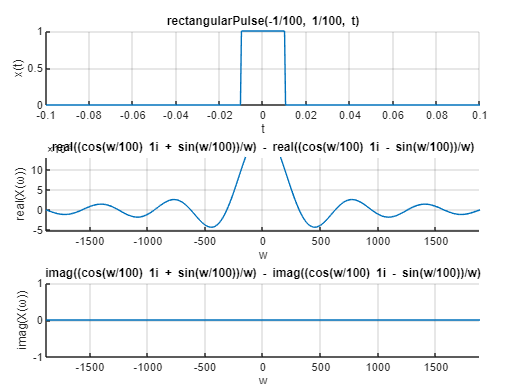

e) impuls trójkątny (symetryczny) o amplitudzie 1 oraz czasie trwania Ti = 2/f`0` .

clear all;
close all;

syms t x f0 w w0 X_FT

f0 = 100; %Hz
w0 = 2*pi*f0;

BND_t = [-10/f0;10/f0]; %20 okresow
t_SMP = [BND_t(1):1/(10*f0):BND_t(2) ];

BND_w = [-3*w0;3*w0];
w_SMP = [BND_w(1):w0/10:BND_w(2) ];

%x = triangularPulse(-1/f0, 1/f0, t);

% fragment kodu odpowiedzialny za impulsy Diraca
% zakomentowany = 1; odkomentowany = 0
commentSignal = 0;
commentReal = 0;
commentImag = 0;

figure
subplot(3,1,1);
ylabel('x(t)');
hold on
ezplot(x,BND_t);
hold on;
grid on;

if commentSignal == 0
    v_num = subs(x, t, t_SMP);
    n = find(abs(v_num) == inf); % plot dirac (inf)
    stem(t_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
end

subplot(3,1,2);
ylabel('real(X(\omega))');
hold on
if commentReal == 0
    v_num = subs(real(X_FT),w,w_SMP);
    n = find(abs(v_num) == inf); % plot dirac(inf)
    stem(w_SMP(n)/2/pi,pi*sign(v_num(n)), 'r*', 'LineWidth', 2);
end
ezplot(real(X_FT), BND_w); 
hold on;
grid on;


subplot(3,1,3);
ylabel('imag(X(\omega))');
hold on
ezplot(imag(X_FT), BND_w);
if commentImag == 0
    v_num = subs(imag(X_FT),w,w_SMP);
    n = find(abs(v_num) == inf); % plot dirac(inf)
    stem(w_SMP(n)/2/pi,pi/4*sign(v_num(n)), 'r*', 'LineWidth', 2);
end
hold on;
grid on

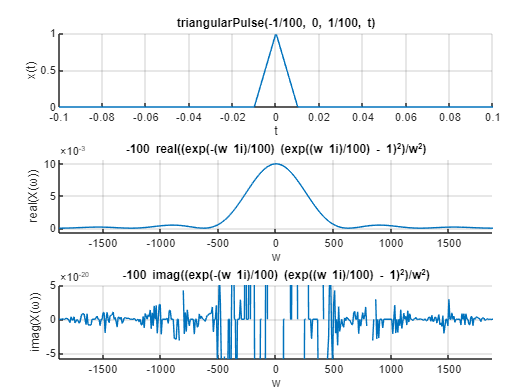

### ZD1

 Dla przebiegów cos(ω0t) oraz sin(ω0t) sporządź również wykresy gęstości widmowej amplitudy oraz fazy. 

clear all;
close all;

syms t x f0 w w0 X_FT

f0 = 100; %Hz
w0 = 2*pi*f0;

BND_t = [-10/f0;10/f0]; %20 okresow
t_SMP = [BND_t(1):1/(10*f0):BND_t(2) ];

BND_w = [-3*w0;3*w0];
w_SMP = [BND_w(1):w0/10:BND_w(2) ];

%x = sin(w0*t);

X_FT = fourier(x);
A = abs(X_FT); % gestosc widmowa mocy
fi = angle(X_FT);

% fragment kodu odpowiedzialny za impulsy Diraca
% zakomentowany = 1; odkomentowany = 0
commentA = 0;
commentFi = 0;

figure(2);

subplot(2,1,1);
ezplot(A,BND_w/2/pi);
hold on;
grid on;

if commentA == 0
    v_num = subs(A,w,w_SMP);
    n = find(abs(v_num) == inf); % plot dirac(inf)
    stem(w_SMP(n)/2/pi,pi*sign(v_num(n)), 'r*', 'LineWidth', 2);
end

ylabel('A(\omega)');
ylim([-0.001 3.5]);
 
subplot(2,1,2);
ezplot(fi,(BND_w/2/pi)');
hold on;
grid on;

if commentFi == 0
    v_num = subs(fi,w,w_SMP);
    n = find(abs(v_num) == inf); % plot dirac(inf)
    stem(w_SMP(n)/2/pi, pi*sign(v_num(n)), 'r*', 'LineWidth', 2);
end

 stem(-100, pi/2, 'r*', 'LineWidth', 2);
 stem(100, -pi/2, 'r*', 'LineWidth', 2);
 ylim([-pi pi]);
 xlabel('f [Hz]');
 ylabel('\phi(\omega)');

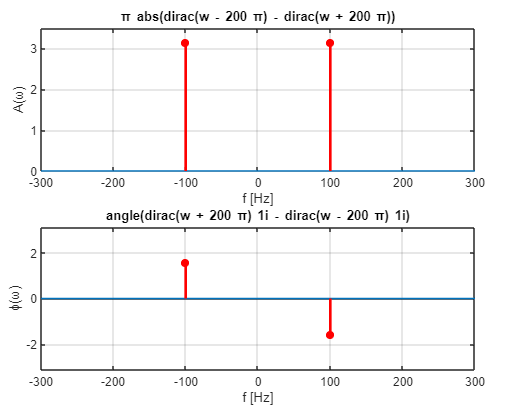

clear all;
close all;

syms t x f0 w w0 X_FT

f0 = 100; %Hz
w0 = 2*pi*f0;

BND_t = [-10/f0;10/f0]; %20 okresow
t_SMP = [BND_t(1):1/(10*f0):BND_t(2) ];

BND_w = [-3*w0;3*w0];
w_SMP = [BND_w(1):w0/10:BND_w(2) ];

%x = cos(w0*t);

X_FT = fourier(x);
A = abs(X_FT); % gestosc widmowa mocy
fi = angle(X_FT);

% fragment kodu odpowiedzialny za impulsy Diraca
% zakomentowany = 1; odkomentowany = 0
commentA = 0;
commentFi = 0;

figure(2);

subplot(2,1,1);
ezplot(A,BND_w/2/pi);
hold on;
grid on;

if commentA == 0
    v_num = subs(A,w,w_SMP);
    n = find(abs(v_num) == inf); % plot dirac(inf)
    stem(w_SMP(n)/2/pi,pi*sign(v_num(n)), 'r*', 'LineWidth', 2);
end

ylabel('A(\omega)');
ylim([-0.001 3.5]);
 
subplot(2,1,2);
ezplot(fi,(BND_w/2/pi)');
hold on;
grid on;

if commentFi == 0
    v_num = subs(fi,w,w_SMP);
    n = find(abs(v_num) == inf); % plot dirac(inf)
    stem(w_SMP(n)/2/pi, pi*sign(v_num(n)), 'r*', 'LineWidth', 2);
end

 stem(-100, pi/2, 'r*', 'LineWidth', 2);
 stem(100, -pi/2, 'r*', 'LineWidth', 2);
 ylim([-pi pi]);
 xlabel('f [Hz]');
 ylabel('\phi(\omega)');

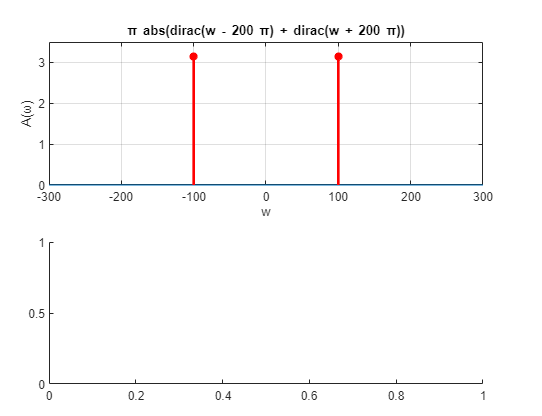

Gęstość widmowa amplitudy dla sinusa oraz cosinusa jest taka sama. Dla cosinusa są one rzeczywiste, stąd faza jest zerem, Na wykresie nic się nie znajduje gdyż matlab wyświetlał błąd. Dla sinusa występują jednak jako liczby urojone, dlatego też ich kąt wynosi 90 i -90 stopni

### 2.3 Zadanie 3

Przeprowadź modulację sygnału cos(ω0t) przebiegiem sinusoidalnym o częstotliwości 10-krotnie mniejszej, amplitudzie 1 i głębokości modulacji m = 0.5. Wyznacz transformatę Fouriera sygnału zmodulowanego i uzgodnij skalę prążków widma. Kod programu oraz wykresy samieść w sprawozdaniu.

clear all;
close all;

syms t x f0 w w0 X_FT

f0 = 100; %Hz
w0 = 2*pi*f0;

BND_t = [-10/f0;10/f0]; %20 okresow
t_SMP = [BND_t(1):1/(10*f0):BND_t(2) ];

BND_w = [-3*w0;3*w0];
w_SMP = [BND_w(1):w0/10:BND_w(2) ];

% sygnal modulowany
%x = (1 + 0.5*sin(w0/10*t))*cos(w0*t);

% fragment kodu odpowiedzialny za impulsy Diraca
% zakomentowany = 1; odkomentowany = 0
commentSignal = 0;
commentReal = 0;
commentImag = 0;

figure
subplot(3,1,1);
ylabel('x(t)');
hold on
ezplot(x,BND_t);
hold on;
grid on;

if commentSignal == 0
    v_num = subs(x, t, t_SMP);
    n = find(abs(v_num) == inf); % plot dirac (inf)
    stem(t_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
end

subplot(3,1,2);
ylabel('real(X(\omega))');
hold on
if commentReal == 0
    v_num = subs(real(X_FT),w,w_SMP);
    n = find(abs(v_num) == inf); % plot dirac(inf)
    stem(w_SMP(n)/2/pi,pi*sign(v_num(n)), 'r*', 'LineWidth', 2);
end
ezplot(real(X_FT), BND_w); 
hold on;
grid on;


subplot(3,1,3);
ylabel('imag(X(\omega))');
hold on
ezplot(imag(X_FT), BND_w);
if commentImag == 0
    v_num = subs(imag(X_FT),w,w_SMP);
    n = find(abs(v_num) == inf); % plot dirac(inf)
    stem(w_SMP(n)/2/pi,pi/4*sign(v_num(n)), 'r*', 'LineWidth', 2);
end
hold on;
grid on

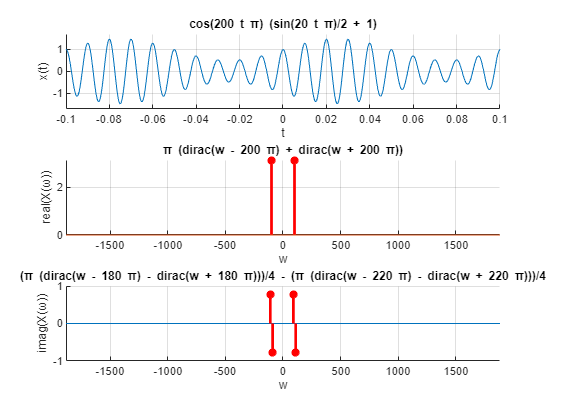

### ZD2 

Porównaj moc sygnału nośnego z mocą wynikowego sygnału zmodulowanego. Napisz w sprawozdaniu jaki wpływ na tę relację ma głębokość modulacji m.

clear all;
close all;

syms T0 f0 w0 t
f0 = 100; %Hz
w0 = 2*pi*f0;
m = [0.0 0.2 0.5 0.6 0.8 1.0];
power = 1:6;
T0 = 1/f0;

% sygnal modulowany
x = (1 + 0.5*sin(w0/10*t))*cos(w0*t);

%sygnał nośny
xn = cos(w0*t);

for i = 1:6
    power(i) = double(f0*int((1+m(i)*xn)*cos(w0*T0)*(1+m(i)*xn)*cos(w0*t),t,[-T0*5 T0*5])/10);
end

moc05 = double(f0*int((x*x),t,[-T0*5 T0*5])/10)

% Moc sygnału nośnego
P_xn = f0 * int(xn^2, t, [0, 1/f0])

% Moc sygnału modulowanego
P_x = f0 / 10 * int(x^2, t, [0, 10/f0])

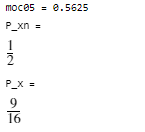

Wraz ze wzrostem współczynnika modulacji rośnie moc.

### 2.4 Zadanie 4 + ZD3

Wyznacz transformatę Fouriera sygnału cos(ω0t) "okienkowanego" tak aby w oknie znajdowało się 6.5 okresów przebiegu To = 6.5/f0. Dzięki temu, przebieg rozpocznie się w obrębie okna i zakończy wartością się wartością zerową. Do okienkowania zastosuj odpowiednio przeskalowane sygnały z Zad. 2:

#### a) impuls prostokątny

clear all; close all;
syms t x f0 w w0 X_FT

f0 = 100; %Hz
w0 = 2*pi*f0;
To = 6.5/f0;

BND_t = [-6.5/(2*f0); 6.5/(2*f0)]; %6.5 okresow
t_SMP = [BND_t(1):1/(10*f0):BND_t(2) ];
BND_w = [-3*w0;3*w0];
w_SMP = [BND_w(1):w0/10:BND_w(2) ];

o = rectangularPulse(-To/2, To/2, t);
x = cos(w0*t);
xo = x*o;
X_FT = fourier(xo);

figure
subplot(3,1,1); ylabel('x(t)'); hold on
ezplot(xo, BND_t); hold on; grid on;
v_num = subs(x, t, t_SMP);
n = find(abs(v_num) == inf); % plot dirac (inf)
stem(t_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);

subplot(3,1,2); ylabel('real(X(\omega))'); hold on
ezplot(real(X_FT), BND_w); hold on; grid on;
ylim([-0.01 0.04])
xlim([-1000 1000])
%v_num = subs(real(X_FT), w, w_SMP);
%n = find( abs(v_num) == inf); % plot dirac (inf)
%stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);

subplot(3,1,3); ylabel('imag(X(\omega))'); hold on
ezplot(imag(X_FT), BND_w); hold on; grid on
%v_num = subs(imag(X_FT), w, w_SMP);
%n = find( abs(v_num) == inf ); % plot dirac (inf)
%stem(w_SMP(n),pi*sign(v_num(n)),'r*', 'LineWidth', 2);
ylim([-4 4]);

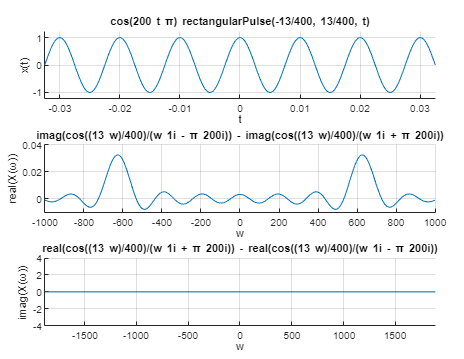

A = abs(X_FT);
figure
ezplot(A, BND_w);
%v_num = subs(A,w,w_SMP);
%n = find(abs(v_num) == inf); % plot dirac(inf)
%stem(w_SMP(n)/2/pi,pi*sign(v_num(n)), 'r*', 'LineWidth', 2);
xlim([-1000 1000]);
ylim([-0.001, 0.035]);

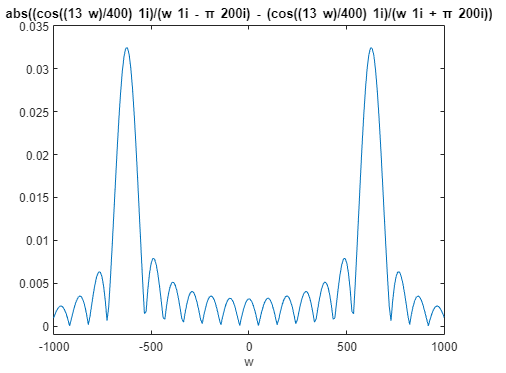

#### b) impuls trójkątny

clear all; close all;
syms t x f0 w w0 X_FT

f0 = 100; %Hz
w0 = 2*pi*f0;
To = 6.5/f0;

BND_t = [-6.5/(2*f0); 6.5/(2*f0)]; %6.5 okresow
t_SMP = [BND_t(1):1/(10*f0):BND_t(2) ];
BND_w = [-3*w0;3*w0];
w_SMP = [BND_w(1):w0/10:BND_w(2) ];

o = triangularPulse(-To/2, To/2, t);
x = cos(w0*t);
xo = x*o;
X_FT = fourier(xo);

figure
subplot(3,1,1); ylabel('x(t)'); hold on
ezplot(xo, BND_t); hold on; grid on;
v_num = subs(x, t, t_SMP);
n = find(abs(v_num) == inf); % plot dirac (inf)
stem(t_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);

subplot(3,1,2); ylabel('real(X(\omega))'); hold on
ezplot(real(X_FT), BND_w); hold on; grid on;
ylim([-0.01 0.04])
xlim([-1000 1000])
ylim([-0.005 0.020]);

subplot(3,1,3); ylabel('imag(X(\omega))'); hold on
ezplot(imag(X_FT), BND_w); hold on; grid on

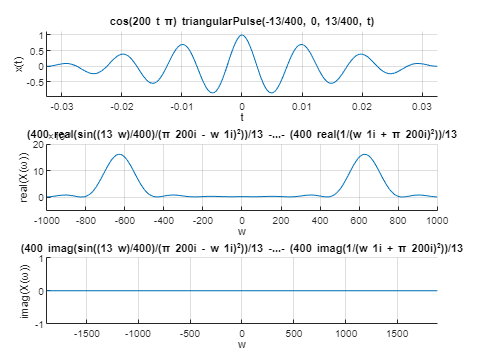

A = abs(X_FT);
figure
ezplot(A, BND_w);
xlim([-1000 1000]);
ylim([-0.001, 0.020]);
grid on

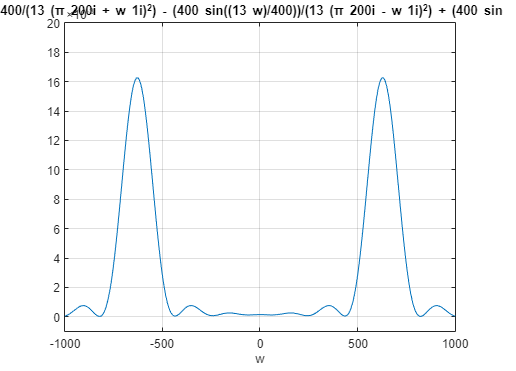

#### c) Krzywa Gaussa 

clear all; close all;
syms t x f0 w w0 X_FT

f0 = 100; %Hz
w0 = 2*pi*f0;
To = 6.5/f0;
c = To/2;

BND_t = [-6.5/(2*f0); 6.5/(2*f0)]; % 6.5 okresow
t_SMP = [BND_t(1):1/(10*f0):BND_t(2) ];
BND_w = [-3*w0;3*w0];
w_SMP = [BND_w(1):w0/10:BND_w(2) ];

o = exp(-t.^2/(2*c.^2));
x = cos(w0*t);
xo = x*o;
X_FT = fourier(xo);

figure
subplot(3,1,1); ylabel('x(t)'); hold on
ezplot(xo, BND_t); hold on; grid on;
%v_num = subs(xo, t, t_SMP);
%n = find(abs(v_num) == inf); % plot dirac (inf)
%stem(t_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);

subplot(3,1,2); ylabel('real(X(\omega))'); hold on
ezplot(real(X_FT), BND_w); hold on; grid on;
ylim([-0.01 2*pi*0.01])
xlim([-1000 1000])
%v_num = subs(real(X_FT), w, w_SMP);
%n = find( abs(v_num) == inf); % plot dirac (inf)
%stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);

subplot(3,1,3); ylabel('imag(X(\omega))'); hold on
ezplot(imag(X_FT), BND_w); hold on; grid on
%v_num = subs(imag(X_FT), w, w_SMP);
%n = find( abs(v_num) == inf ); % plot dirac (inf)
%stem(w_SMP(n),pi*sign(v_num(n)),'r*', 'LineWidth', 2);
ylim([-4 4]);

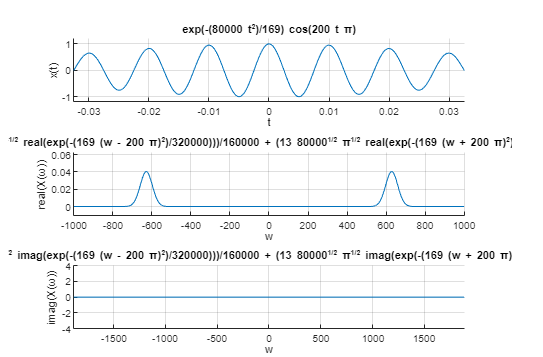

A = abs(X_FT);
figure
ezplot(A, BND_w);
%v_num = subs(A,w,w_SMP);
%n = find(abs(v_num) == inf); % plot dirac(inf)
%stem(w_SMP(n)/2/pi,pi*sign(v_num(n)), 'r*', 'LineWidth', 2);
xlim([-1000 1000]);
ylim([-0.001, 0.042]);